This script is going to be used to analyze the results from the combined experiment. First, we load in the time synched and merged data from the experiment.

load('ExperimentData_CombinedExperiment_Merged_2023_04_08.mat');

Now, let's take a look at the trajectory that the chaser (red) and target (blue) platforms took. We can see that the target stayed central, as designed. Meanwhile, red moves in position and then starts to track the target in a circle. The circle is rather messy, but this is because of the poor acceleration controller.

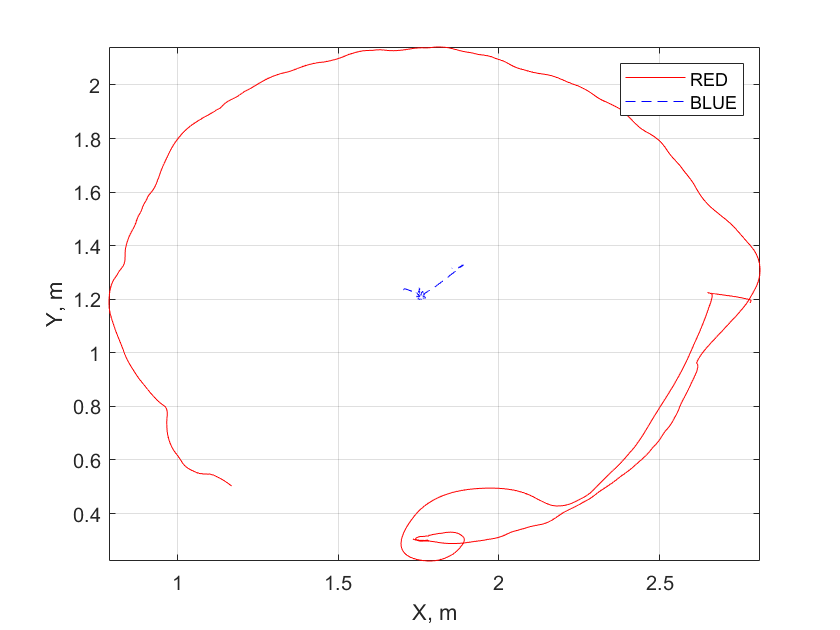

figure()
plot(dataClass.RED_Px_m(200:end), dataClass.RED_Py_m(200:end),'-r')
hold on
grid on
axis tight
plot(dataClass.BLUE_Px_m(200:end), dataClass.BLUE_Py_m(200:end),'--b')
xlabel('X, m')

ylabel('Y, m')
legend('RED','BLUE','location','northeast')

We can also check the arm maneuver. The deployment was successfully completed, and the commanded position and measured position of the joints align well. The is a bit of a delay between the commanded and actual measurement,  but this makes sense give the slow encoder data collection rate.

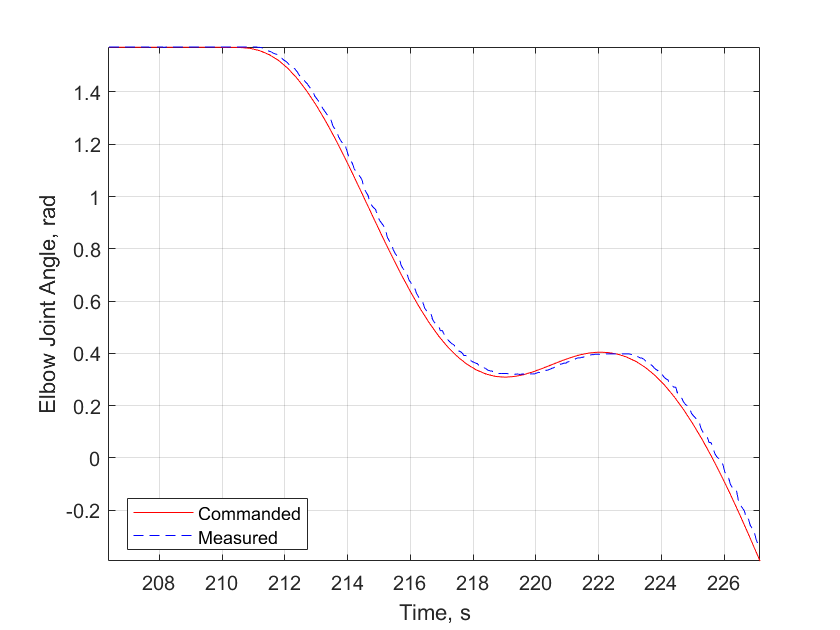

figure()
plot(dataClass.Time_s(3400:3732), dataClass.ARM_Elbow_Commanded_Nm(3400:3732),'-r')
hold on
grid on
axis tight
plot(dataClass.Time_s(3400:3732), dataClass.ARM_Elbow_Rz_rad(3400:3732),'--b')
xlabel('Time, s')   
ylabel('Elbow Joint Angle, rad')
legend('Commanded','Measured','location','best')

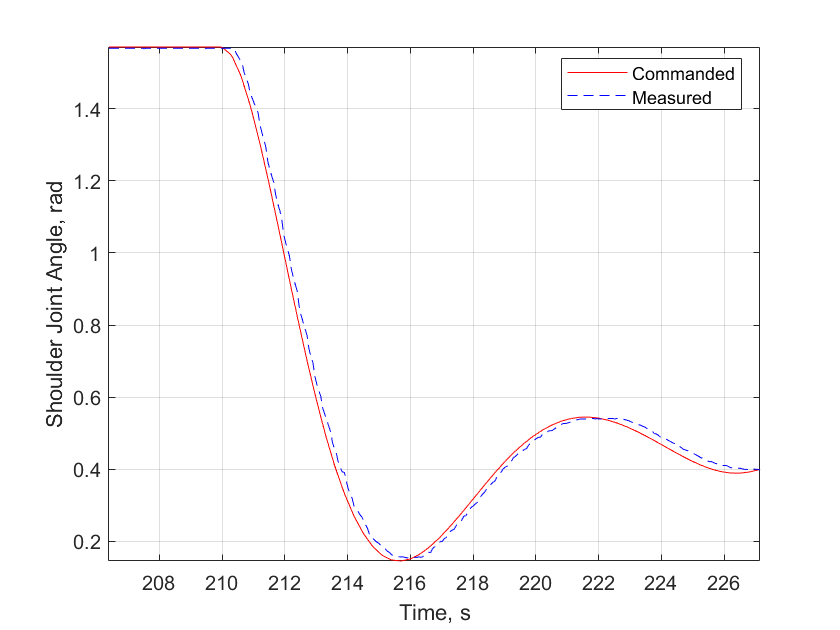

figure()
plot(dataClass.Time_s(3400:3732), dataClass.ARM_Shoulder_Commanded_Nm(3400:3732),'-r')
hold on
grid on
axis tight
plot(dataClass.Time_s(3400:3732), dataClass.ARM_Shoulder_Rz_rad(3400:3732),'--b')
xlabel('Time, s')
ylabel('Shoulder Joint Angle, rad')
legend('Commanded','Measured','location','best')

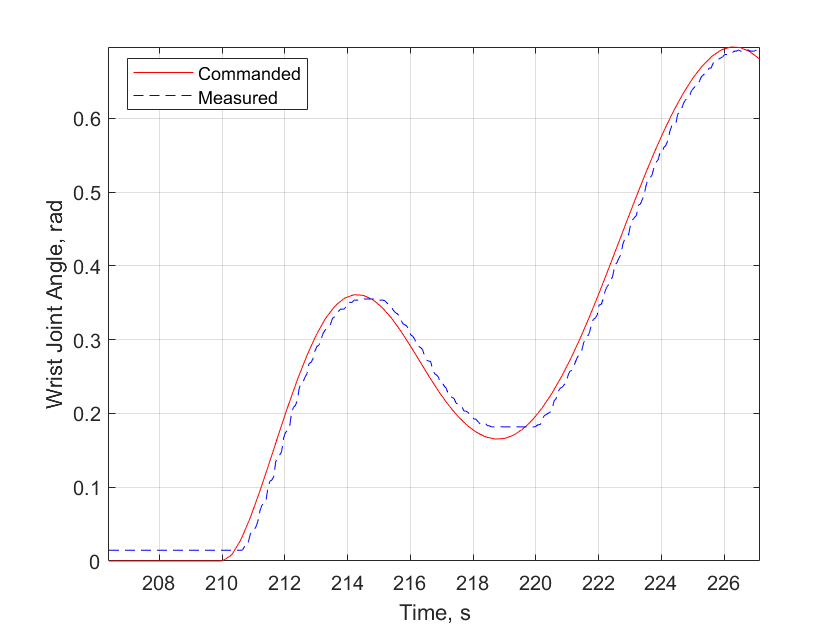

figure()
plot(dataClass.Time_s(3400:3732), dataClass.ARM_Wrist_Commanded_Nm(3400:3732),'-r')
hold on
grid on
axis tight
plot(dataClass.Time_s(3400:3732), dataClass.ARM_Wrist_Rz_rad(3400:3732),'--b')
xlabel('Time, s')
ylabel('Wrist Joint Angle, rad')
legend('Commanded','Measured','location','best')

Plotting the performance of the machine vision measurements shows good correlation between the actual relative positions (per the phasespace system) and the measurements made by the camera. Tracking starts to fail after the target has been capture likely due to the introduction of the arm into the view. Will have to check the cameras, but the chaser may have also rotated a bit and the camera might have lost sight of the target. The loss of the target is especially evident in the attitude estimation.

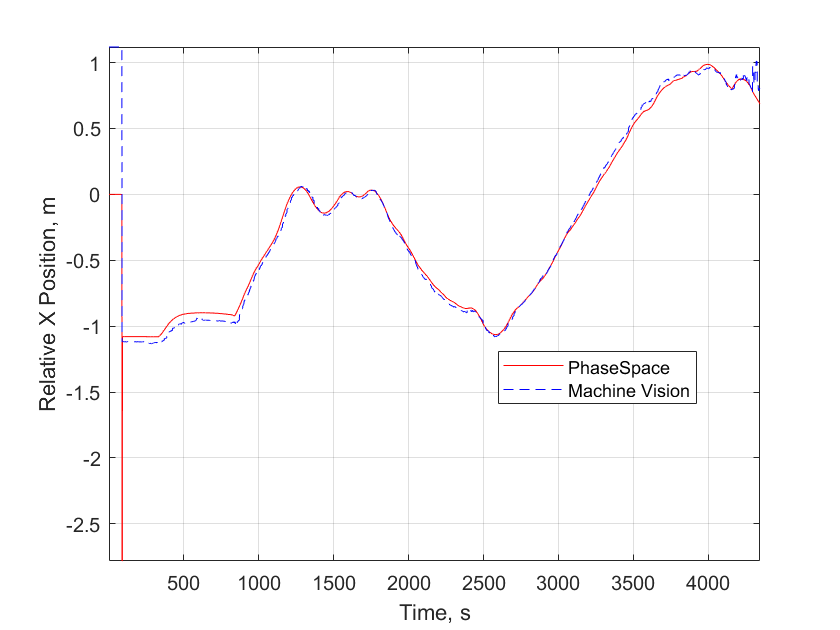

relative_pose_inertial = [dataClass.BLUE_Px_m - dataClass.RED_Px_m, dataClass.BLUE_Py_m - dataClass.RED_Py_m, dataClass.BLUE_Rz_m - dataClass.RED_Rz_m];
 

SPOTNet_target_x_inertial = dataClass.RED_Px_m + dataClass.ZED_Relative_X_m.*cos(dataClass.RED_Rz_m) - dataClass.ZED_Relative_Y_m.*sin(dataClass.RED_Rz_m);
SPOTNet_target_y_inertial = dataClass.RED_Py_m + dataClass.ZED_Relative_X_m.*sin(dataClass.RED_Rz_m) + dataClass.ZED_Relative_Y_m.*cos(dataClass.RED_Rz_m);
SPOTNet_target_angle_inertial = dataClass.RED_Rz_m + dataClass.ZED_Relative_Yaw_rad;

relative_pose_inertial_ZED = [SPOTNet_target_x_inertial - dataClass.RED_Px_m, SPOTNet_target_y_inertial - dataClass.RED_Py_m, SPOTNet_target_angle_inertial - dataClass.RED_Rz_m];     

figure()
plot(dataClass.Time_s,relative_pose_inertial(:,1),'-r')
hold on
grid on
axis tight
plot(dataClass.Time_s,relative_pose_inertial_ZED(:,1),'--b')
xlabel('Time, s')
ylabel('Relative X Position, m')
legend('PhaseSpace','Machine Vision','location','best')

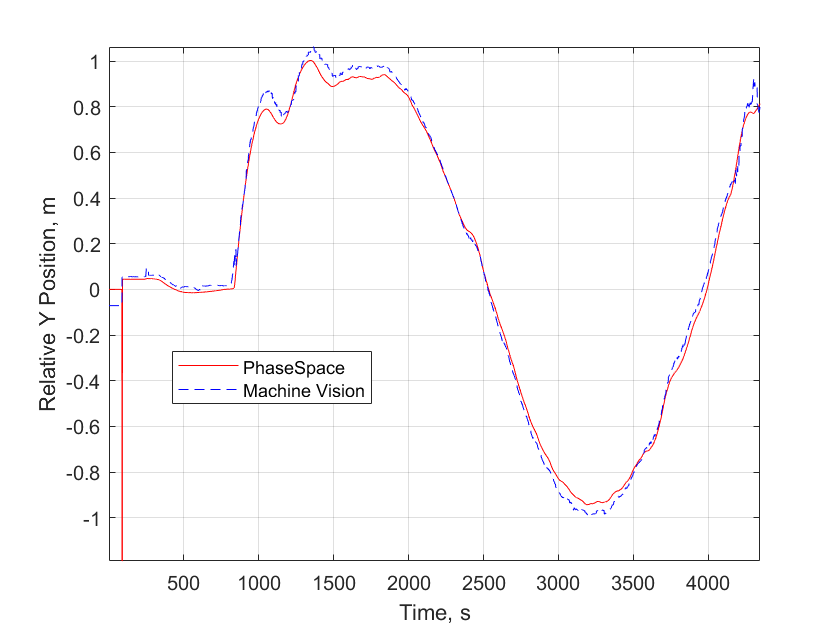


figure()
plot(dataClass.Time_s,relative_pose_inertial(:,2),'-r')
hold on
grid on
axis tight
plot(dataClass.Time_s,relative_pose_inertial_ZED(:,2),'--b')
xlabel('Time, s')
ylabel('Relative Y Position, m')
legend('PhaseSpace','Machine Vision','location','best')

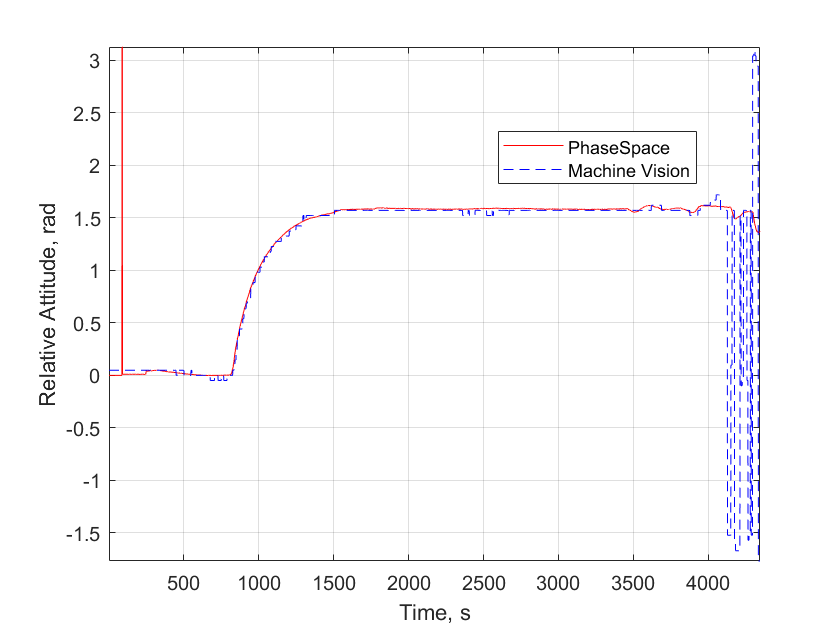


figure()
plot(dataClass.Time_s,relative_pose_inertial(:,3),'-r')
hold on
grid on
axis tight
plot(dataClass.Time_s,relative_pose_inertial_ZED(:,3),'--b')
xlabel('Time, s')
ylabel('Relative Attitude, rad')
legend('PhaseSpace','Machine Vision','location','best')

Let's check the attitude displacement. The optimal displacement may be difficult to discern as the motion is intended to match the rate of rotation for the satellite. But, we can see that the attitude displacement rate is quite linear (as designed). So the platform ends it's maneuver still being closely aligned with the attitude of the target.

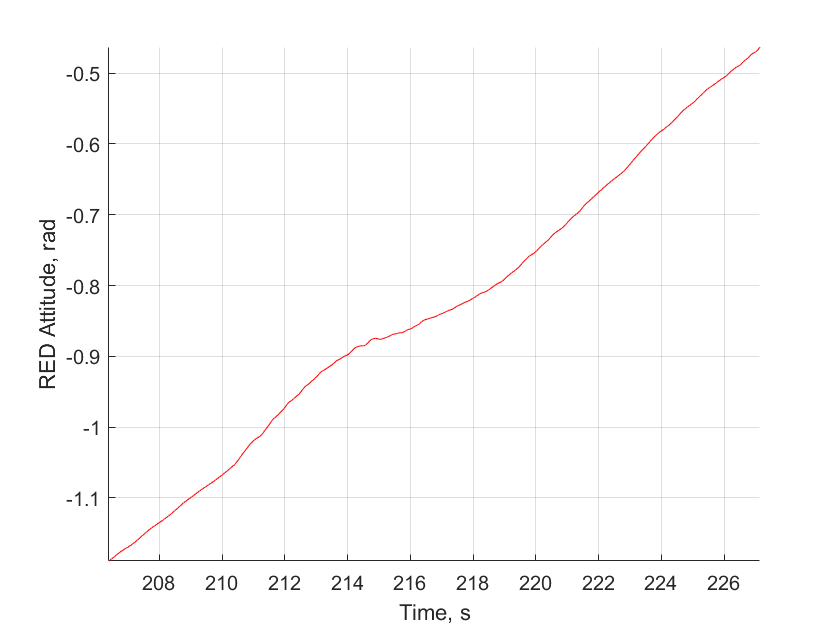

figure()
hold on
grid on
axis tight
plot(dataClass.Time_s(3400:3732),dataClass.RED_Rz_m(3400:3732),'-r')
xlabel('Time, s')
ylabel('RED Attitude, rad')

%legend('PhaseSpace','Machine Vision','location','best')